filename="transmissionCasingData.csv";
tbl = readtable(filename,'TextType','String');

labelName='GearToothCondition';
tbl=convertvars(tbl,labelName,'categorical');

categoricalInputNames=["SensorCondition" "ShaftCondition"];
tbl=convertvars(tbl,categoricalInputNames,'categorical');

for i = 1:numel(categoricalInputNames)
    name = categoricalInputNames(i);
    oh = onehotencode(tbl(:,name));
    tbl = addvars(tbl,oh,'After',name);
    tbl(:,name) = [];
end

tbl=splitvars(tbl);

classNames=categories(tbl{:,labelName})

classNames = 2×1 cell 数组
    {'No Tooth Fault'}
    {'Tooth Fault'   }


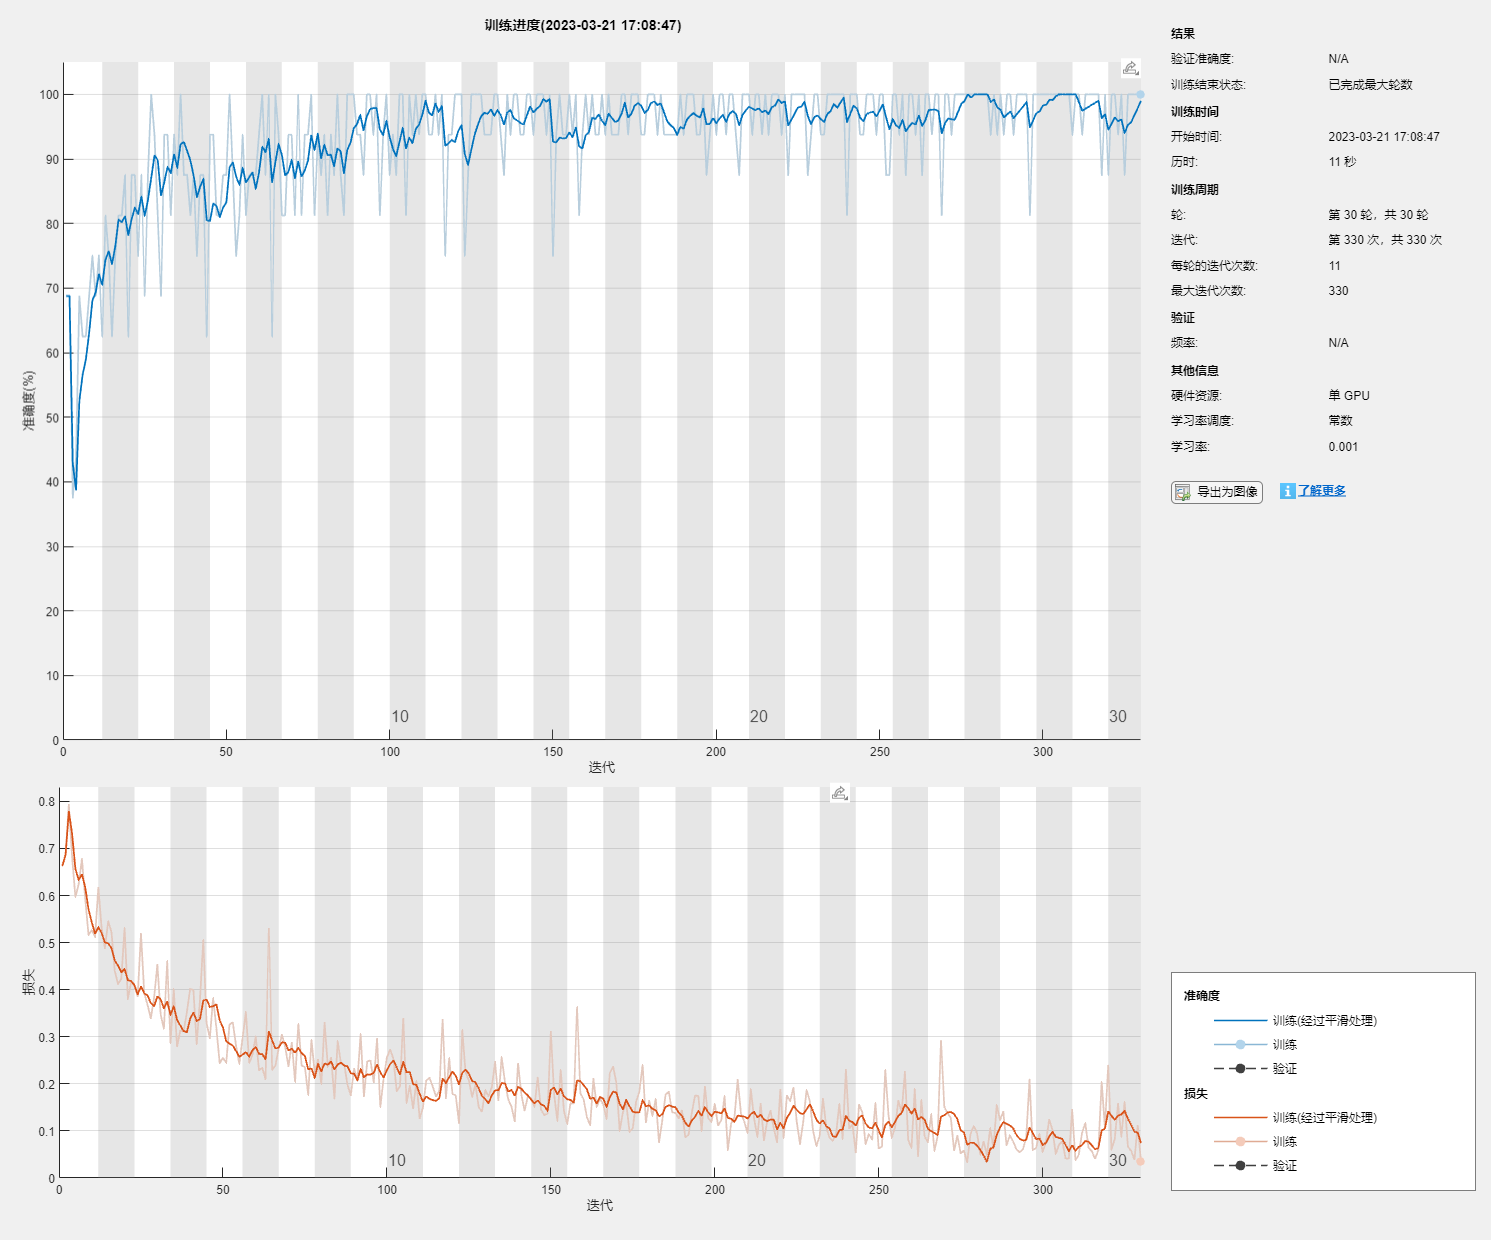

numObservations = size(tbl,1);
numObservationsTrain = floor(0.85*numObservations);
numObservationsTest = numObservations - numObservationsTrain;

idx = randperm(numObservations);
idxTrain = idx(1:numObservationsTrain);
idxTest = idx(numObservationsTrain+1:end);

tblTrain=tbl(idxTrain,:);
tblTest=tbl(idxTest,:);

numFeatures = size(tbl,2) - 1;
numClasses = numel(classNames);

layers = [
    featureInputLayer(numFeatures,'Normalization', 'zscore')
    fullyConnectedLayer(50)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

miniBatchSize = 16;

options = trainingOptions('adam', ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false);

net = trainNetwork(tblTrain,layers,options);



YPred = classify(net,tblTest,'MiniBatchSize',miniBatchSize);
YTest = tblTest{:,labelName};

accuracy = sum(YPred == YTest)/numel(YTest)

accuracy =        0.9375
